Open it as live script!!!

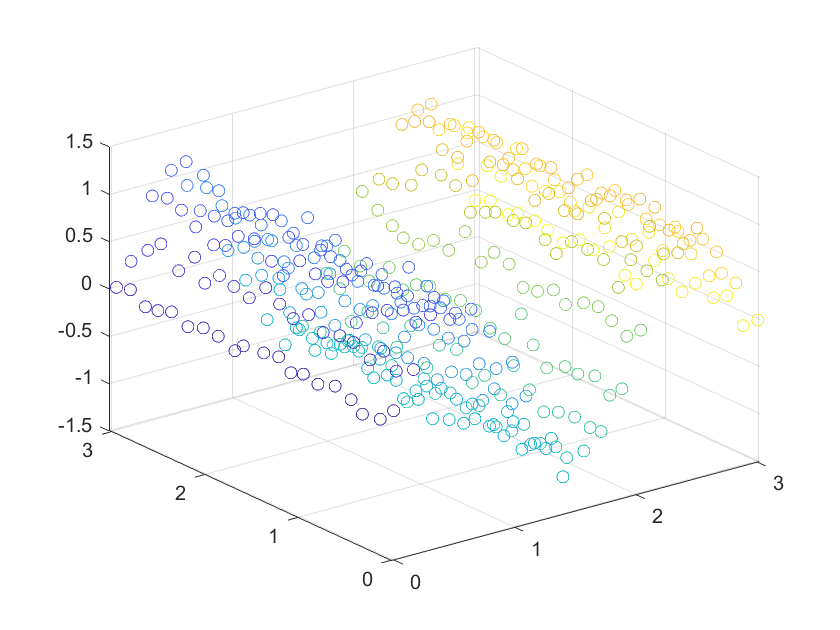

clear;
x = linspace(0, 3, 20);
y = linspace(0, 3, 20);
[x, y] = meshgrid(x, y);
x = x + randn(size(x)) * 0.01;
y = y + randn(size(y)) * 0.01;
z = sin(1 * pi * (x)) + randn(size(x)) * 0.1;

X = [x(:), y(:), z(:)];
c = (1:length(X)) / length(X);
clear x y z;
scatter3(X(:, 1), X(:, 2), X(:, 3), [], c);

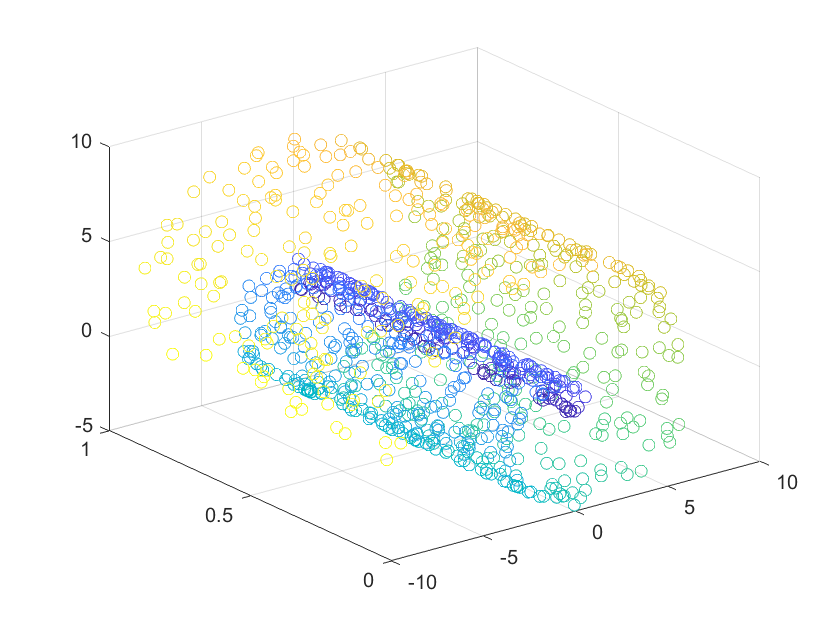

%瑞士卷的生成图
N = 1000;
t = linspace(0, 3 * pi, N)' + 0.01 * randn(N, 1);
s = rand(N, 1);
X=[t.*cos(t), s, t.*sin(t)];
c = (1:length(X)) / length(X);
scatter3(X(:, 1), X(:, 2), X(:, 3), [], c)

k = 10; d = 2;
y = LLE(X, k, d);

scatter(y(:, end), y(:, end-1), [], c);